% PART 0: ASSUMPTIONS
% 1. Air is in-compressible (density is constant)
% 2. Air density and dynamic viscosity remain constant
% 3. Flow is steady: velocity and pressure at a fixed location do not vary with time
% 4. Temperature effects neglected
% 5. Idealized One-Dimensional / Uniform Velocity Profile (boundary layers, shear stress, spatial velocity gradients are ignored)

% PART 1: DEFINING PARAMETERS & ENVIRONMENT

% Aerodynamic Constants (SI Units)
air_density = 1.225;              % kg/m^3
dynamic_viscosity = 1.81e-5;      % Pa*s 

% Velocity Vector
velocity = 5:1:30;                % m/s

% Test Section
width = 0.095;                    % m
height = 0.095;                   % m
characteristic_length = 2 * width * height / (width + height);    % Test section hydraulic diameter

% PART 2: AERODYNAMIC EQUATIONS

% Reynolds Number Vector
reynolds_number = (air_density * velocity * characteristic_length) / dynamic_viscosity;

% Dynamic Pressure Vector
dynamic_pressure = 0.5 * air_density * (velocity .^ 2);

% PART 3: 1D SPATIAL ANALYTICAL MODEL
% Modeling how flow changes physically down the length of the wind tunnel.

% Lengths of tunnel sections [m]
L_contraction = 0.234247;           % Length of contraction nozzle
L_test = 0.31;                      % Length of test section
L_diffuser = 0.233928;              % Length of diffuser


% Continuous spatial coordinate vector (x-axis along tunnel centerline)
x_contraction = linspace(0, L_contraction, 60);
x_test = linspace(L_contraction, L_contraction + L_test, 40);
x_diffuser = linspace(L_contraction + L_test, L_contraction + L_test + L_diffuser, 60);
x_axis = [x_contraction, x_test(2:end), x_diffuser(2:end)];


% Cross-sectional geometry along tunnel
% Contraction Section
width_start = 0.125197;                 
height_start = 0.125305;
 
% Test Section
width_test = width;   
height_test = height; 

% Diffuser Section
width_exit = 0.125306;   
height_exit = 0.125306;


% Cross-sectional area A(x) profile along the whole tunnel
Area = zeros(size(x_axis));
for i = 1:length(x_axis)
    xi = x_axis(i);
    if xi <= L_contraction
        % Contraction: smoothly shrinks from start size down to test size
        fraction = xi / L_contraction;
        w_curr = width_start - (width_start - width_test) * (1 - cos(fraction * pi)) / 2;
        h_curr = height_start - (height_start - height_test) * (1 - cos(fraction * pi)) / 2;
        Area(i) = w_curr * h_curr;

    elseif xi <= (L_contraction + L_test)
        % Test Section: constant cross-sectional area
        Area(i) = width_test * height_test;

    else
        % Diffuser: smoothly expands from test size out to exit size
        fraction = (xi - (L_contraction + L_test)) / L_diffuser;
        w_curr = width_test + (width_exit - width_test) * (1 - cos(fraction * pi)) / 2;
        h_curr = height_test + (height_exit - height_test) * (1 - cos(fraction * pi)) / 2;
        Area(i) = w_curr * h_curr;
    end
end


% Applying 1D Continuity Equation & Bernoulli to all test speeds 
A_test = width_test * height_test;

% Matrices - Rows: test section speed, columns: position along tunnel
velocity_spatial        = velocity(:) * (A_test ./ Area);
pressure_static_spatial = 0.5*air_density*velocity(:).^2 - 0.5*air_density*velocity_spatial.^2;

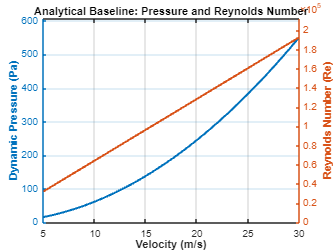

% PART 4: VISUALIZATION 1

% Reynolds Number and Dynamic Pressure vs. Velocity Plot

figure('Name', 'Flow Parameters vs Velocity', 'Color', 'white');

% Left Y-Axis for Dynamic Pressure
yyaxis left
plot(velocity, dynamic_pressure, 'LineWidth', 2);
ylabel('Dynamic Pressure (Pa)', 'FontWeight', 'bold');
ylim([0, max(dynamic_pressure) * 1.1]); % Add a little headroom

% Right Y-Axis for Reynolds Number
yyaxis right
plot(velocity, reynolds_number, 'LineWidth', 2);
ylabel('Reynolds Number (Re)', 'FontWeight', 'bold');
ylim([0, max(reynolds_number) * 1.1]);

% Shared X-Axis
xlabel('Velocity (m/s)', 'FontWeight', 'bold');
title('Analytical Baseline: Pressure and Reynolds Number');
grid on;

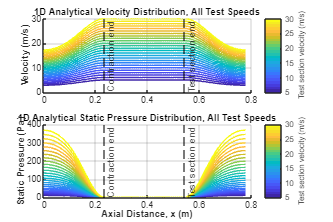

% PART 5: VISUALIZATION 2 

% Velocity distribution and Pressure Distribution against distance plot

figure('Name', '1D Spatial Profiles, All Speeds', 'Color', 'white', 'Position', [150 150 900 600]);
cmap = parula(numel(velocity));

% Subplot 1: velocity along tunnel, one curve per test speed
subplot(2,1,1);
hold on
for k = 1:numel(velocity)
    plot(x_axis, velocity_spatial(k,:), 'LineWidth', 1.5, 'Color', cmap(k,:));
end
hold off
ylabel('Velocity (m/s)', 'FontWeight', 'bold');
title('1D Analytical Velocity Distribution, All Test Speeds');
grid on;
colormap(gca, cmap);
cb = colorbar; cb.Label.String = 'Test section velocity (m/s)';
clim([min(velocity) max(velocity)]);
xline(L_contraction, '--k', 'Contraction end');
xline(L_contraction + L_test, '--k', 'Test section end');

% Subplot 2: static pressure along tunnel
subplot(2,1,2);
hold on
for k = 1:numel(velocity)
    plot(x_axis, pressure_static_spatial(k,:), 'LineWidth', 1.5, 'Color', cmap(k,:));
end
hold off
xlabel('Axial Distance, x (m)', 'FontWeight', 'bold');
ylabel('Static Pressure (Pa)', 'FontWeight', 'bold');
title('1D Analytical Static Pressure Distribution, All Test Speeds');
grid on;
colormap(gca, cmap);
cb = colorbar; cb.Label.String = 'Test section velocity (m/s)';
clim([min(velocity) max(velocity)]);
xline(L_contraction, '--k', 'Contraction end');
xline(L_contraction + L_test, '--k', 'Test section end');

% PART 6: ANALYTICAL RESULTS TABLE

results = table(velocity(:), dynamic_pressure(:), reynolds_number(:), velocity_spatial(:,1), pressure_static_spatial(:,1), ...
    'VariableNames', {'V_test(m/s)', 'q_test(Pa)','Re_test', 'V_inlet(m/s)', 'P_inlet_rel_test(Pa)'});

disp(results)                                   % command window output

    V_test(m/s)    q_test(Pa)     Re_test      V_inlet(m/s)    P_inlet_rel_test(Pa)
    ___________    __________    __________    ____________    ____________________

         5           15.313           32148       2.8764              10.245       
         6            22.05           38577       3.4517              14.752       
         7           30.013           45007        4.027               20.08       
         8             39.2           51436       4.6023              26.227       
         9           49.613           57866       5.1776              33.193       
        10            61.25           64296       5.7529              40.979       
        11           74.113           70725       6.3282              49.585       
        12             88.2           77155       6.9034               59

writetable(results, 'analytical_results.csv');  % csv file